clear
% simultion of 6 metagriding

## constants


eta = 377; %ohm
f= 10*10^9; %Hz
c = 3*10^8; %m/s
lambda = c/f;
k = 2*pi/lambda;
omega = 2*pi*f;
w = 3*0.0254e-3; % meters, 3 mil
reff = w/4;
epsilon=8.85e-12;


## paramters


theta_in = 10*pi/180; %rads
theta_out = 70*pi/180;% rads
phi = 25*pi/180; % rads
Ein = 1;

sinin = sin(theta_in);
cosin = cos(theta_in);
sinout = sin(theta_out);
cosout = cos(theta_out);

Zin = eta/cos(theta_in);
Zout = eta/cos(theta_out);
Eout = Ein*sqrt(cosin/cosout);
Lambda = lambda/abs(sinout-sinin);

deltaRes=18.3e-3*eta/lambda; %resistence of copper wire

## Optimization parameters

numOfIter=100;% how maney random starting conditions to check
N=1000; % to what degree to calculate the infinate sums 
weigt=0.5;%how much to consider power lost and how much 
save('var.mat');
best.Zs=zeros(6,1);% the best results with only capacitance tipe impidances
best.PowerLost=inf;
best.CopperPowerLost=inf;
best.Ds=zeros(1,6);
best.Hs=zeros(1,6);
best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);

## Optimization

i=1; %index
total=0;% for percentage of good ones
while i<=numOfIter 
    total=total+1;
    % initial position
    x0=[Lambda*rand(1,5),lambda*rand(1,5)];
    Ds= [0 x0(1:5)];
    Hs= [0 x0(6:10)];
    Is =  FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
    Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
    Zs = Fields./Is;
    if imag(Zs)<0
        % Set nondefault solver options
        options = optimoptions('fmincon','Display','off');
        
        % Solve
        [solution,objectiveValue] = fmincon(@objectiveFcn,x0,[],[],[],[],[],[],...
            @constraintFcn,options);
        
        % Clear variables
        clearvars options
        Ds = [0 solution(1:5)];
        Hs = [0 solution(6:10)];
        Is =  FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
        Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
        Zs = Fields./Is;
        objective = objectiveFcn(solution)
        if imag(Zs)<0
             i=i+1%go on with the index
        end
        if objective<best.PowerLost+weigt*best.CopperPowerLost % is it the best result so far?
            
          if imag(Zs)<0
              best.PowerLost=1/2*(abs(Is).^2).*real(Zs);
              best.CopperPowerLost=1/2*abs(Is).^2*deltaRes;
              best.Ds=[0,solution(1:5)];
              best.Hs=[0,solution(6:10)];
              best.Is=FindCurrents(best.Ds,best.Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
              best.Zs=FindElectricField(Lambda,k,eta,theta_in,theta_out,Ein,best.Ds,best.Hs,best.Is,reff,N,'Poisson')./best.Is;
          end
        end
    end
end

objective = 1.3427e-04

i = 2

objective = 2.9337e-04

i = 3

objective = 7.0082e-05

i = 4

objective = 0.0026

i = 5

objective = 1.9583e-04

i = 6

objective = 9.3687e-05

i = 7

objective = 3.7438e-05

i = 8

objective = 0.0024

i = 9

objective = 3.0033e-05

i = 10

objective = 9.3394e-05

i = 11

objective = 1.9051e-05

i = 12

objective = 2.5941e-05

i = 13

objective = 1.8051e-04

i = 14

objective = 2.9154e-04

i = 15

objective = 5.3621e-04

i = 16

objective = 2.3234e-04

i = 17

objective = 0.0016

i = 18

objective = 2.4321e-04

i = 19

objective = 1.3571e-04

i = 20

objective = 7.8141e-04

i = 21

objective = 1.1084e-04

i = 22

objective = 1.6250e-05

i = 23

objective = 6.1080e-05

i = 24

objective = 4.3456e-05

i = 25

objective = 9.6885e-05

i = 26

objective = 2.2781e-04

i = 27

objective = 8.8624e-05

i = 28

objective = 5.2868e-04

i = 29

objective = 1.6891e-04

i = 30

objective = 1.0972e-04

i = 31

objective = 1.7494e-04

i = 32

objective = 2.3157e-05

i = 33

objective = 0.0041

i = 34

objective = 7.4372e-05

i = 35

objective = 3.4624e-05

i = 36

objective = 1.5380e-04

i = 37

objective = 3.4672e-05

i = 38

objective = 4.6027e-05

i = 39

objective = 3.4311e-04

i = 40

objective = 1.8439e-05

i = 41

objective = 9.0470e-05

i = 42

objective = 2.5861e-04

i = 43

objective = 1.7047e-04

i = 44

objective = 1.5239e-04

i = 45

objective = 1.5014e-04

i = 46

objective = 5.7462e-05

i = 47

objective = 4.5384e-05

i = 48

objective = 9.1120e-05

i = 49

objective = 1.3438e-05

i = 50

objective = 9.9824e-05

i = 51

objective = 6.1466e-05

i = 52

objective = 3.2857e-04

i = 53

objective = 1.7244e-05

i = 54

objective = 3.1203e-05

i = 55

objective = 5.7221e-05

i = 56

objective = 1.0574e-04

i = 57

objective = 1.8304e-04

i = 58

objective = 1.3469e-04

i = 59

objective = 7.6325

objective = 1.5490e-04

i = 60

objective = 8.5480e-05

i = 61

objective = 5.5089e-05

i = 62

objective = 1.2351e-04

i = 63

objective = 2.4065e-04

i = 64

objective = 1.7913e-05

i = 65

objective = 3.4147e-04

i = 66

objective = 1.2844e-04

i = 67

objective = 4.9275e-04

i = 68

objective = 4.1770e-05

i = 69

objective = 3.4982e-05

i = 70

objective = 2.9108e-04

i = 71

objective = 9.6967e-04

i = 72

objective = 1.3776e-05

i = 73

objective = 6.4701e-05

i = 74

objective = 4.3064e-05

i = 75

objective = 1.0038e-04

i = 76

objective = 4.9927e-05

i = 77

objective = 4.0975e-04

i = 78

objective = 1.3657e-04

i = 79

objective = 4.0694e-04

i = 80

objective = 1.2565e-04

i = 81

objective = 2.9662e-04

i = 82

objective = 2.9484e-05

i = 83

objective = 1.3264e-04

i = 84

objective = 2.1592e-04

i = 85

objective = 3.7749e-05

i = 86

objective = 2.6048e-04

i = 87

objective = 0.0075

i = 88

objective = 5.1172e-04

i = 89

objective = 1.8386e-04

i = 90

objective = 0.0025

i = 91

objective = 2.2130e-04

i = 92

objective = 1.2412e-04

i = 93

objective = 3.5537e-05

i = 94

objective = 8.1580e-05

i = 95

objective = 1.9667e-04

i = 96

objective = 9.2536e-05

i = 97

objective = 3.1000e-05

i = 98

objective = 4.8320e-05

i = 99

objective = 0.0041

i = 100

objective = 4.1218e-05

i = 101

## Plots

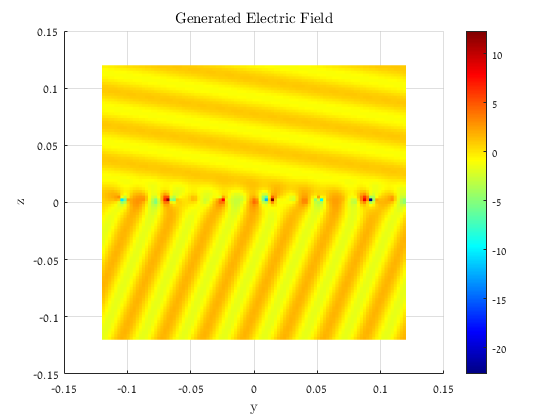


M = 100; %plot resolution
y = linspace(-4*lambda,4*lambda, M)'; % colum vector
z = linspace(-4*lambda,4*lambda, M); % row vector
[TotalElectricFieldMatrix, GeneratedElectricFieldMatrix] = ElectricFieldYZ(best.Is,best.Ds,best.Hs,k,Lambda,y,z,theta_in,Ein,N,eta,theta_out);
PlotField(GeneratedElectricFieldMatrix,y,z,'Generated Electric Field');

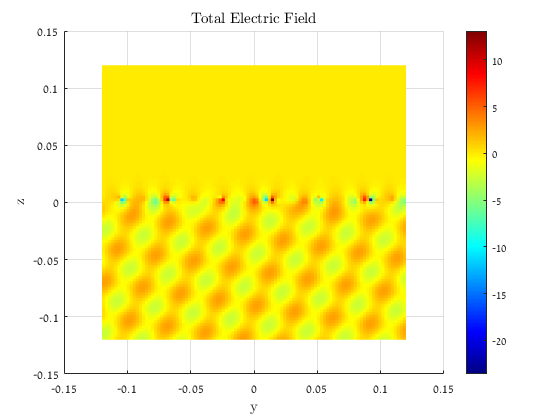

PlotField(TotalElectricFieldMatrix,y,z,'Total Electric Field');

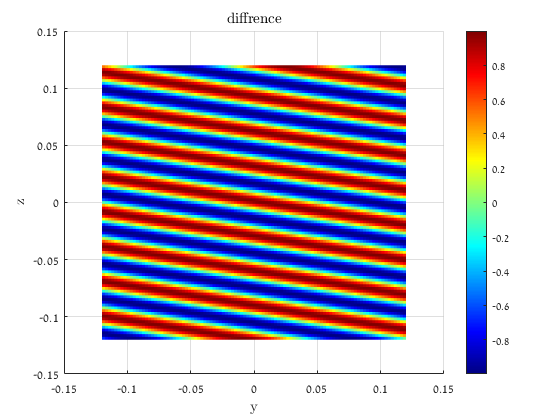

PlotField(TotalElectricFieldMatrix-GeneratedElectricFieldMatrix,y,z,'diffrence');

## normalization

UnitI=Lambda/eta*Ein;
IsNorm=best.Is/UnitI;
DsNorm=best.Ds/Lambda;
HsNorm=best.Hs/Lambda;
PowerIn=1/2/eta*Ein^2*Lambda*cosin;
PowerLost=(1/2*abs(best.Is).^2).*real(best.Zs);
NormPowerLost=PowerLost/PowerIn;
NormCopperPowerLost=best.CopperPowerLost./PowerIn;
NormZs=best.Zs*UnitI;

## optimization function

function f = objectiveFcn(optimInput)

load('var.mat');
% Edit the lines below with your calculation

Ds= [0 optimInput(1:5)];
Hs= [0 optimInput(6:10)];
Is = FindCurrents(Ds,Hs,Lambda,Ein,Eout,Zin,Zout,theta_in,theta_out,k,phi);
Fields = FindElectricFiield(Lambda,k,eta,theta_in,theta_out,Ein,Ds,Hs,Is,reff,N,'Poisson');
Zs= Fields./Is;
f= sum(abs((1/2*abs(Is).^2).*real(Zs)))+weigt*sum(abs((1/2*abs(Is).^2).*deltaRes));% minimum power lost (\gain)
%f= sum(abs(real(Zs)./imag(Zs)));
end


## costrains


function [c,ceq] = constraintFcn(optimInput)
load('var.mat');

% Note, if no equality constraints, specify ceq = []
D2 = optimInput(1);
D3 = optimInput(2);
D4 = optimInput(3);
D5 = optimInput(4);
D6= optimInput(5);
H2 = optimInput(6);
H3 = optimInput(7);
H4 = optimInput(8);
H5 = optimInput(9);
H6 = optimInput(10);


c(1) = H2 - H3;
c(2) = H3 - H4;
c(3) = H4 - H5;
c(4) = H5 - H6;
c(5) = - H2;
c(6) = - D2;
c(7) = - D3;
c(8) = - D4;
c(9) = - D5;
c(10) = - D6;
c(11) = D2 - Lambda;
c(12) = D3 - Lambda;
c(13) = D4 - Lambda;
c(14) = D5 - Lambda;
c(15) = D6 - Lambda;
c(16) = H6 - lambda/10;
ceq = [];
end


